% filename = uigetfile({'*.stl';'*.ply'})
ptCloudWithMarker = stlread("WithMark.stl");
ptCloudWithMark = pointCloud(ptCloudWithMarker.Points)

ptCloudWithMark =   pointCloud のプロパティ:

     Location: [60754×3 double]
        Count: 60754
      XLimits: [-0.0564 0.0644]
      YLimits: [-0.0214 0.1194]
      ZLimits: [-0.1284 0.3671]
        Color: []
       Normal: []
    Intensity: []


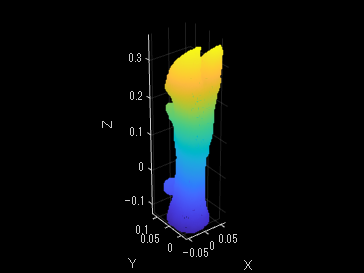

pcshowWithAxes(ptCloudWithMark)

% ptCloudWithMark = import3Dmodel(filename, true);

maxDist = 0.0001;
[model, inlierIn, out] = pcfitsphere(ptCloudWithMark, maxDist, 'MaxNumTrials',50000);

selectSphere = select(ptCloudWithMark, inlierIn);
outSphere = select(ptCloudWithMark, out)

outSphere =   pointCloud のプロパティ:

     Location: [59728×3 double]
        Count: 59728
      XLimits: [-0.0564 0.0644]
      YLimits: [-0.0214 0.1194]
      ZLimits: [-0.1284 0.3671]
        Color: []
       Normal: []
    Intensity: []


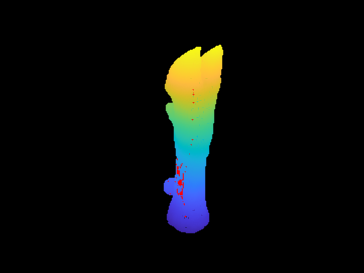

pcshow(ptCloudWithMark, "AxesVisibility","on");
hold on;
pcshow(selectSphere.Location, 'r');
hold off;

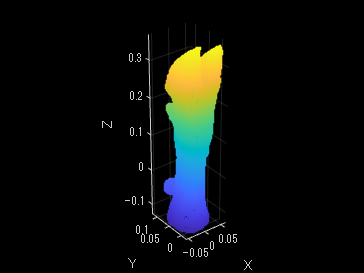

pcshowWithAxes(outSphere);

figure();
pcshowWithAxes(ptCloudWithMark);

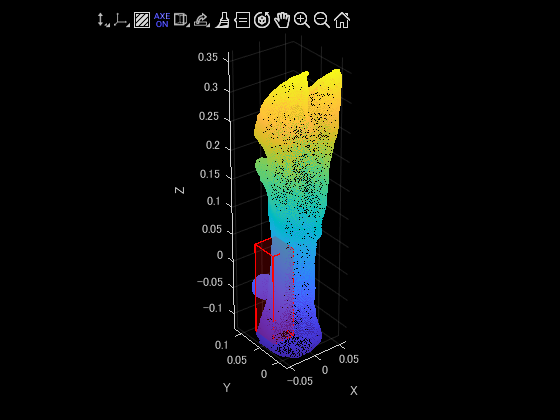

ax = gca;
roi = images.roi.Cuboid(ax, 'Rotatable', 'all', 'Color', 'r');
draw(roi);

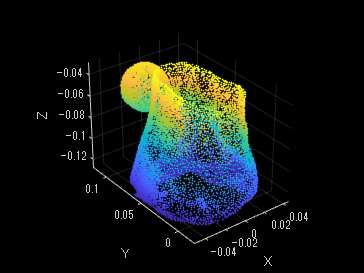

xmin = roi.Position(1);
ymin = roi.Position(2);
zmin = roi.Position(3);
xmax = roi.Position(4)+roi.Position(1);
ymax = roi.Position(5)+roi.Position(2);
zmax = roi.Position(6)+roi.Position(3);

newroi = [xmin xmax ymin ymax zmin zmax];
indices = findPointsInROI(ptCloudWithMark, newroi);
newPoint = select(ptCloudWithMark, indices);
pcshowWithAxes(newPoint);

maxDist = 0.0025;
[model2, inlierIn2, out2] = pcfitsphere(ptCloudWithMark, maxDist, 'MaxNumTrials',20000, 'SampleIndices',indices);
seSphere = select(ptCloudWithMark, inlierIn2)

seSphere =   pointCloud のプロパティ:

     Location: [4491×3 double]
        Count: 4491
      XLimits: [-0.0295 0.0101]
      YLimits: [0.0776 0.1194]
      ZLimits: [-0.0765 -0.0360]
        Color: []
       Normal: []
    Intensity: []


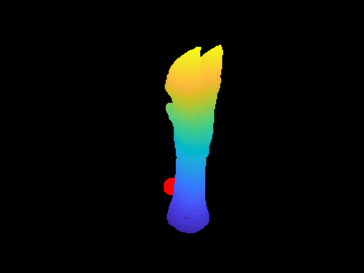

oSphere = select(ptCloudWithMark, out2);
pcshow(ptCloudWithMark, "AxesVisibility","on");
hold on;             
pcshow(seSphere.Location, 'r');
hold off;

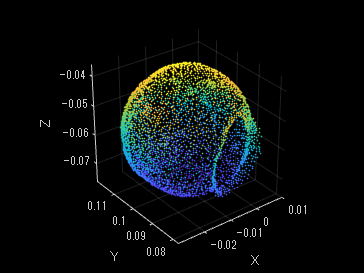

pcshowWithAxes(seSphere);

pcshow(ptCloudWithMark, "AxesVisibility","on");
hold on;
pcshow(seSphere.Location, 'r');
hold off;

edegx = seSphere.XLimits;
e2 = edegx(2);
e1 = edegx(1);
Dia(1) = abs(e2-e1)

Dia = 0.0321


edegy = seSphere.YLimits;
e2y = edegy(2);
e1y = edegy(1);
Dia(2) = abs(e2y-e1y)

Dia =     0.0321    0.1054



edegz = seSphere.ZLimits;
e2z = edegz(2);
e1z = edegz(1);
Dia(3)= abs(e2z-e1z)

Dia =     0.0321    0.1054    0.3296



DiaMean = mean(Dia)

DiaMean = 0.1557

onlyTwoDia = (Dia(1) + Dia(3)) / 2

onlyTwoDia = 0.1809


markerSize = 0.04;

rate = onlyTwoDia/markerSize

rate = 4.5219

newPoint = oSphere.Location * rate

newPoint =    -0.1286   -0.0548    0.9897
   -0.1312   -0.0521    0.9773
   -0.1260   -0.0558    0.9791
   -0.1321   -0.0567    1.0329
   -0.1377   -0.0514    1.0213
   -0.1313   -0.0559    1.0223
   -0.1517   -0.0396    1.0221
   -0.1458   -0.0450    1.0231
   -0.1490   -0.0436    1.0343
   -0.1530   -0.0356    0.9980


oSphere.Location

ans =    -0.0284   -0.0121    0.2189
   -0.0290   -0.0115    0.2161
   -0.0279   -0.0123    0.2165
   -0.0292   -0.0125    0.2284
   -0.0305   -0.0114    0.2259
   -0.0290   -0.0124    0.2261
   -0.0336   -0.0088    0.2260
   -0.0322   -0.0099    0.2263
   -0.0330   -0.0096    0.2287
   -0.0338   -0.0079    0.2207
